clear
subject = "92a04"; ses = "pre";
fileName ="iTBS_"+subject+"_"+ses+".mat";
cd("C:\Users\Katherine\Documents\AAA UW\Herron Lab\Data\" + subject)
load(fileName)

order = 3;
freqs = {.5 200 [53,63] [117,123] [177,183]};
ftype = ["high" "low" "stop" "stop" "stop"];
data_filt = double(data_artrem);
for i=1:length(freqs)
    freq = freqs{i};
    [b,a] = butter(order,freq/(fs/2),ftype(i));
%     freqz(b, a, 0:.1:400, fs);
    data_filt = filtfilt(b,a,data_filt);
end

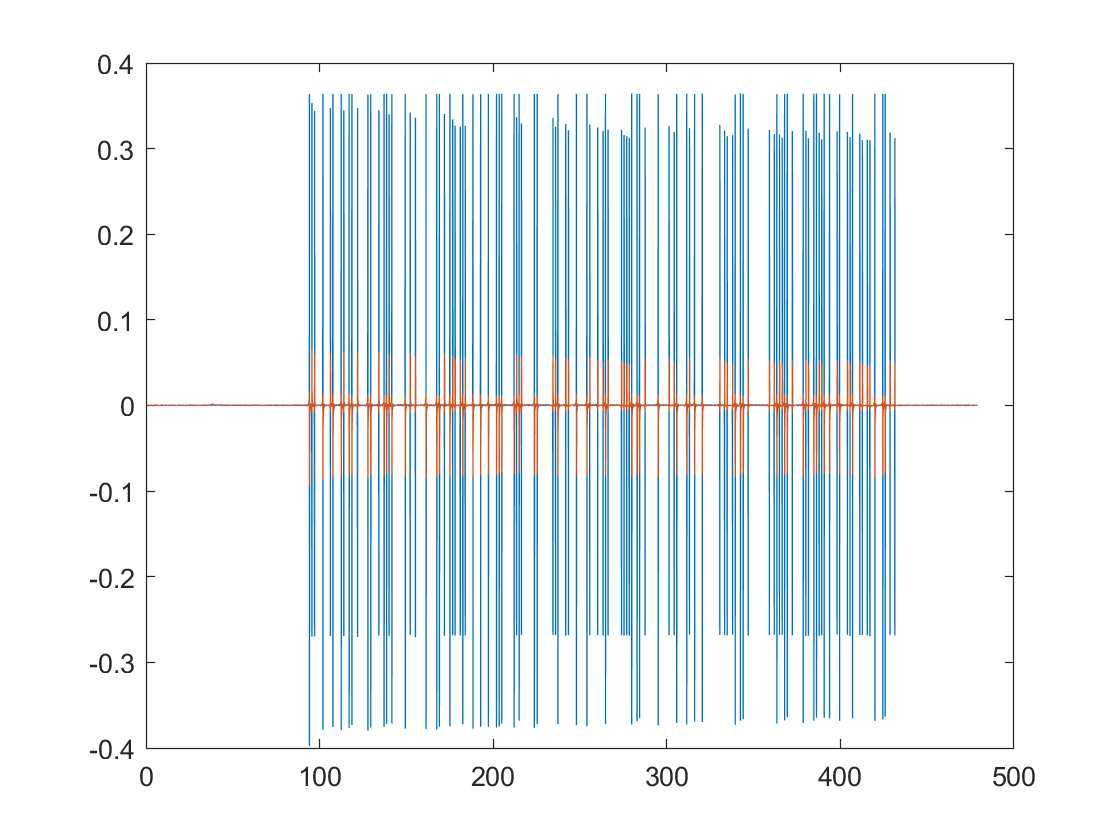

figure()
C_r = 12;
x = linspace(1,length(data_artrem)/fs,length(data_artrem)); % units of time
plot(x,data_artrem(:,C_r))
hold on
plot(x,data_filt(:,C_r))

save(fileName,'data_filt','-append')